# Definición de trayectorias

Dificultad: Normal (no terminado)

## Trayectorias por iteración entre ejes

- Las trayectorias es la obtención de una serie de ejes entre dos dados con diferentes criterios.

- Interpolar entre matrices homogéneas y/o matrices de rotación.

- Se puede interpolar con mayores criterios de velocidad y aceleración.

- Se puede interpolar entre más de dos puntos

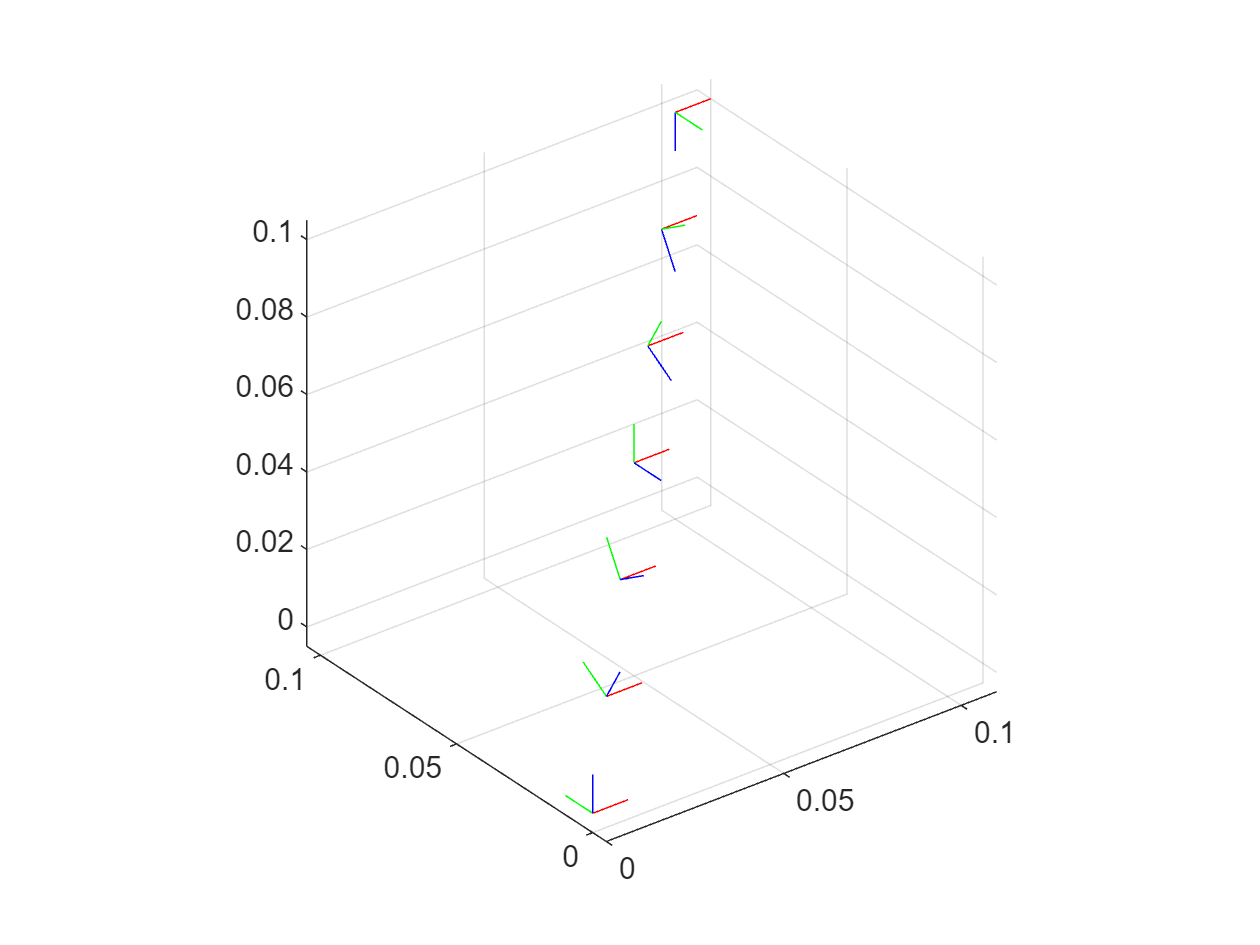

deg= pi/180;
nPts= 7;

H1= se3(Prod([[0,0,0]*1e-3, [0,0,0]*deg]));
H2= se3(Prod([[100,100,100]*1e-3, [0,0,180]*deg]));

H= interp(H1,H2,nPts);
%H= transformtraj(H1, H2, [0,1], 0:0.1:1);
figure
hold on
for i= 1:nPts
   plotTransforms(H(i), 'FrameSize', 10*1e-3);
end

## Trajectory Generation

% Trajectory Generation
%     cubicpolytraj     - Generate third-order polynomial trajectories through multiple waypoints
%     quinticpolytraj   - Generate fifth-order polynomial trajectories through multiple waypoints
%     bsplinepolytraj   - Generate multi-axis trajectories through control points using B-splines
%     transformtraj     - Generate trajectory between two homogeneous transforms
%     trapveltraj       - Generate piecewise polynomials through multiple waypoints using trapezoidal velocity profiles
%     rottraj           - Generate trajectory between two orientations
%     minjerkpolytraj   - Generate minimum jerk trajectories through multiple waypoints
%     minsnappolytraj   - Generate minimum snap trajectories through multiple waypoints
%     contopptraj       - Create constrained time-optimal path parametrized trajectory
 

% waypointTrajectory	Waypoint trajectory generator
% kinematicTrajectory	Rate-driven trajectory generator